% Define symbolic variables for state-space representation
syms s x1 x2 r;

%% 1. Define System Matrices
A = [1 1; 1 2];
B = [1; 0];
C = [1 0];

% Display the state-space matrices
disp('System Matrices:');

System Matrices:


disp('A:'); disp(A);

A:
     1     1
     1     2



disp('B:'); disp(B);

B:
     1
     0



disp('C:'); disp(C);

C:
     1     0




%% 2. Check Reachability
Wr = [B A*B]; % Reachability matrix
rankWr = rank(Wr);

disp('Reachability Matrix:');

Reachability Matrix:


disp(Wr);

     1     1
     0     1



disp(['Rank of Reachability Matrix: ', num2str(rankWr)]);

Rank of Reachability Matrix: 2



if rankWr == size(A, 1)
    disp('The system is reachable.');
else
    disp('The system is NOT reachable.');
    return;
end

The system is reachable.



%% 3. Desired Closed-Loop Characteristic Polynomial
p_desired = [1 5 6]; % Desired polynomial coefficients for (s + 2)(s + 3)
disp('Desired Closed-Loop Characteristic Polynomial:');

Desired Closed-Loop Characteristic Polynomial:


disp(poly2sym(p_desired, s));

$$s^{2}+5\,s+6$$


%% 4. Compute Feedback Gains using Pole Placement
p_actual = poly(A); % Open-loop characteristic polynomial
disp('Open-Loop Characteristic Polynomial:');

Open-Loop Characteristic Polynomial:


disp(poly2sym(p_actual, s));

$$s^{2}-3\,s+1$$


% Solve for K using pole placement
K = place(A, B, [-2, -3]); % Desired poles at s = -2, s = -3
disp('State Feedback Gain K:');

State Feedback Gain K:


disp(K);

    8.0000   21.0000




%% 5. Compute Reference Gain (k_fr)
k_fr = 1 / (C * inv(-A + B*K) * B);
disp('Reference Gain k_fr:');

Reference Gain k_fr:


disp(k_fr);

   -3.0000




%% 6. Implement Control Law
syms u;
u = -K * [x1; x2] + k_fr * r;
disp('Control Law u:');

Control Law u:


disp(u);

$$-3\,r-8\,x_{1}-21\,x_{2}$$


%% 7. Verify Closed-Loop System
A_cl = A - B * K; % Closed-loop A matrix
B_cl = B * k_fr;  % Input matrix adjusted for reference tracking
disp('Closed-Loop System Matrices:');

Closed-Loop System Matrices:


disp('A_cl:'); disp(A_cl);

A_cl:
   -7.0000  -20.0000
    1.0000    2.0000



disp('B_cl:'); disp(B_cl);

B_cl:
   -3.0000
         0



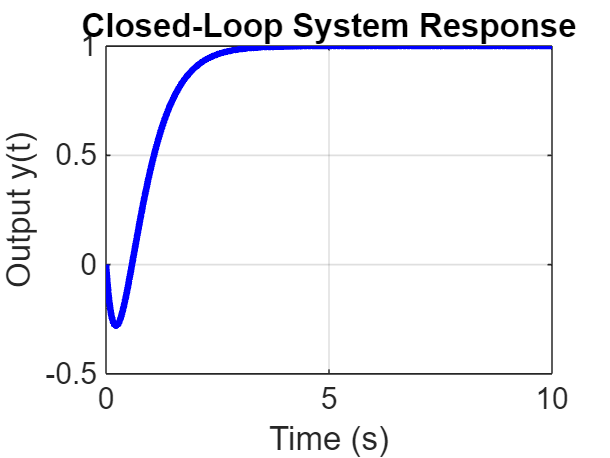


%% 8. Simulate System (Optional)
% Define time vector and initial conditions
t = 0:0.01:10; % Time from 0 to 10 seconds
x0 = [0; 0]; % Initial state

% Define input r (reference signal)
r = 1; % Step reference

% Define closed-loop system
sys_cl = ss(A_cl, B_cl, C, 0); % State-space closed-loop system

% Simulate response
[y, t_out, x] = lsim(sys_cl, r*ones(size(t)), t, x0);

% Plot results
figure;
plot(t_out, y, 'b', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Output y(t)');
title('Closed-Loop System Response');
grid on;